# Classify human electrocardiogram (ECG) Signals

wise 2023

Name : Sai Sricharan Sammeta

matriculation number : 1010394

Given is the following ECG signal

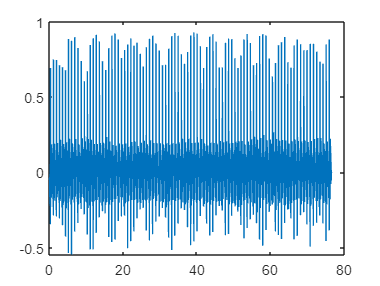

close all
clear all
% load ecg signal 
ecg =load('ecg.mat');
% Graphical Output
% Time Signal
t = [0:length(ecg.data)-1]/ecg.fs;
plot(t,ecg.data)

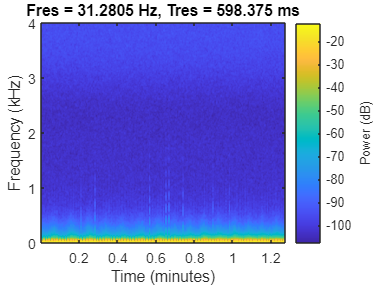

% Short Time Fourier Analysis -- Spectrogram
pspectrum(ecg.data,ecg.fs,'spectrogram')

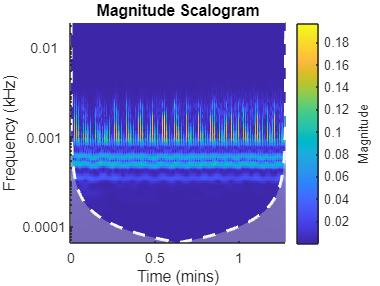

% Wavelet Analysis -- Scalogram
cwt(ecg.data,[],ecg.fs)

In general people can be devided in three groups:

- persons with cardiac arrhythmia (ARR)

- persons with congestive heart failure (CHF), and

- persons with normal sinus rhythms (NSR). 

The goal of this PStA is to classify human electrocardiogram (ECG) signals using the Short Time Fourier Transformation and the Continuous Wavelet Transform (CWT) and deep convolutional neural networks (CNNs). The resulting CNNs shall be used to classify the given ECG signal to ARR, CHF, and NSR, respectively. 

### Matlab Example

The Matlab Example [Classify Time Series Using Wavelet Analysis and Deep Learning - MATLAB & Simulink Example - MathWorks Deutschland](https://de.mathworks.com/help/releases/R2020b/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html) can be taken as a basis. It uses ECG data (the training and test data are publicly available from [PhysioNet](https://physionet.org/)) obtained from three groups of people: persons with cardiac arrhythmia (ARR), persons with congestive heart failure (CHF), and persons with normal sinus rhythms (NSR). In total  162 ECG recordings from three PhysioNet databases are used: [MIT-BIH Arrhythmia Database](https://www.physionet.org/physiobank/database/mitdb/) , [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/physiobank/database/nsrdb/) , and [The BIDMC Congestive Heart Failure Database](https://www.physionet.org/physiobank/database/chfdb/); more specifically, 96 recordings from persons with arrhythmia, 30 recordings from persons with congestive heart failure, and 36 recordings from persons with normal sinus rhythms. Two deep CNNs, GoogLeNet and SqueezeNet, pretrained for image recognition, are adapted to classify ECG waveforms based on a time-frequency representation -- the Wavelet Transformation.

## Tasks

- Complete the Live Script

- Dokument and explain your code with theoretical background -- detailed and understandable -- within the Live Script. Use additional plottings.

- Dokumentation and transparent coding has an important impact on the mark!

- Use the following time-frequency representations and investigate the impact on the ECG classification: Short Time Fourier Transformation and Wavelet Transformation

- Use the following pretrained deep CNNs and compare the results for the ECG classification; GoogLeNet, SqueezeNet and AlexNet.

## Data Preprocessing & Datastore

Generate the time-frequency representation using

- Short Time Fourier Transformation and

- Wavelet Transformation

and generate the corresponding data stores.

Compare the impact on the CNNs by comparing the confusion charts!

% This code loads ECG data from the file 'ECGData.mat'.
% It then extracts the 'Data' and 'Labels' variables from the loaded data.
% The 'Data' variable contains ECG signals that are used to train and test ECG classification models,
% while the 'Labels' variable contains the corresponding labels indicating the classes of the ECG signals. 
% The code further creates three subsets of the ECG data based on the classes of the signals.
% The first subset, 'ARR', contains the first 30 ECG signals from the data, which belong to the 'ARR' class. 
% The second subset, 'CHF', 
% contains the 30 ECG signals from the 'CHF' class, 
% which are located from the 97th to 126th position in the original data. 
% The third subset, 'NSR', 
% contains the 30 ECG signals from the 'NSR' class, 
% which are located from the 127th to 156th position in the original data. 
% Finally, the code defines a variable 'signallength' with a value of 500. 
% The purpose of this variable is not clear from this code snippet,
% but it may be used elsewhere in the program.

load('ECGData.mat')
data = ECGData.Data;
labels = ECGData.Labels;


ARR = data(1:30,:);
CHF = data(97:126,:);
NSR = data(127:156,:);
signallength = 500;


% This code segment performs the following tasks:
%
% 1.It loads the ECGData.mat file which contains ECG data and corresponding labels.
% 2.It extracts the ECG data for three types of heartbeats: ARR, CHF, and NSR.
% 3.It creates a Continuous Wavelet Transform (CWT) filter bank object for signal length of 500 
% and wavelet type amor with 12 voices per octave.
% 4.It creates folders named 'ecgdataset', 'ecgdataset\arr', 'ecgdataset\chf', 
% and 'ecgdataset\nsr' to store CWT transformed ECG images.
% 5.It calls the function ecg2cwtscg to convert ECG signals to CWT 
% transformed images and stores them in the respective folders.
% 6.It creates folders named 'ecgdataset_stft', 'ecgdataset_stft\arr', 
% 'ecgdataset_stft\chf', and 'ecgdataset_stft\nsr' 
% to store Short-time Fourier Transform (STFT) transformed ECG images.
% 7.It calls the function ecg2stft to convert ECG signals to STFT 
% transformed images and stores them in the respective folders.

fb= cwtfilterbank('SignalLength', signallength, 'Wavelet','amor','VoicesPerOctave',12);

%making folders
mkdir('ecgdataset');   %main folder
mkdir('ecgdataset\arr');  %subfolders
mkdir('ecgdataset\chf');
mkdir('ecgdataset\nsr');

ecgtype = {'ARR','CHF','NSR'};

%function to convert ECG to image
ecg2cwtscg(ARR, fb, ecgtype{1});

nos = 10

nol = 500

ecg2cwtscg(CHF, fb, ecgtype{2});

nos = 10

nol = 500

ecg2cwtscg(NSR, fb, ecgtype{3});

nos = 10

nol = 500



%making folders
mkdir('ecgdataset_stft');   %main folder
mkdir('ecgdataset_stft\arr');  %subfolders
mkdir('ecgdataset_stft\chf');
mkdir('ecgdataset_stft\nsr');

ecgtype = {'ARR','CHF','NSR'};

%function to convert ECG to image
ecg2stft(ARR, fb, ecgtype{1});

nos = 10

nol = 500

fs = 256

ecg2stft(CHF, fb, ecgtype{2});

nos = 10

nol = 500

fs = 256

ecg2stft(NSR, fb, ecgtype{3});

nos = 10

nol = 500

fs = 256

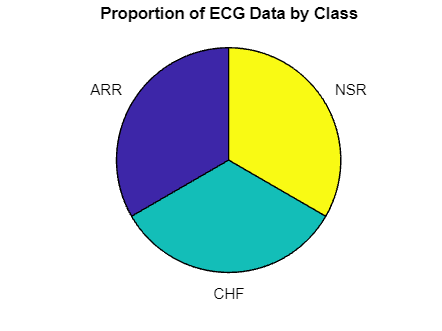

% This code calculates the number of samples in each class (ARR, CHF, and NSR) of the ECG data 
% and then calculates the proportion of each class. 
% It then creates a pie chart showing the proportion of each class. 
% The size() function is used to count the number of samples in each class, 
% and the proportions are calculated by dividing the count of each class by the total number of samples. 
% Finally, the pie() function is used to create the pie chart, 
% with the proportions vector as the first argument and the labels vector as the second argument. 
% The title of the pie chart is set to "Proportion of ECG Data by Class" using the title() function.

% Count the number of samples in each class
n_arr = size(ARR,1);
n_chf = size(CHF,1);
n_nsr = size(NSR,1);

% Calculate the proportion of each class
prop_arr = n_arr / (n_arr + n_chf + n_nsr);
prop_chf = n_chf / (n_arr + n_chf + n_nsr);
prop_nsr = n_nsr / (n_arr + n_chf + n_nsr);

% Create a pie chart
labels = {'ARR', 'CHF', 'NSR'};
proportions = [prop_arr, prop_chf, prop_nsr];
pie(proportions, labels);
title('Proportion of ECG Data by Class');

% The above code loads the CWT and STFT images that were generated from ECG signals 
% using the respective functions ecg2cwtscg and ecg2stft.
% For each set of images, it creates an imageDatastore object 
% which reads images from the specified directory and treats the subfolders as different labels. 
% The IncludeSubfolders option is set to true to include images in subfolders. 
% The LabelSource option is set to 'foldernames' to automatically assign labels to images 
% based on the subfolder they are in.
% The splitEachLabel function splits the images in each label into two sets: 
% a training set and a testing set. 
% The numTrainFiles argument specifies the number of images in the training set for each label. 
% The 'randomized' option means that the function shuffles the images before splitting them.


% reading cwt images
DatasetPath = 'C:\Users\charan sammeta\Desktop\DSP\project\ecgdataset';
% Reading images from image database folder
images_cwt = imageDatastore(DatasetPath, "IncludeSubfolders",true,'LabelSource','foldernames');
% Distributing images in the set of training and testing
numTrainFiles = 250;
[TrainImages_cwt, TestImages_cwt] = splitEachLabel(images_cwt,numTrainFiles,'randomized');


% reading stft images
DatasetPath = 'C:\Users\charan sammeta\Desktop\DSP\project\ecgdataset_stft';
% Reading images from image database folder
images_stft = imageDatastore(DatasetPath, "IncludeSubfolders",true,'LabelSource','foldernames');
% Distributing images in the set of training and testing
numTrainFiles = 250;
[TrainImages_stft, TestImages_stft] = splitEachLabel(images_stft,numTrainFiles,'randomized');


% The code is creating augmented image datastores for the training and testing datasets 
% of the CWT images and STFT images separately. 
% The augmentedImageDatastore function is used to rescale the images to 
% match the input size required by the GoogLeNet model, which is [224 224]. 
% This function applies data augmentation techniques such as resizing, cropping, 
% and rotation to the images in the datastores. 
% The resulting TrainImages_cwt_aug, TestImages_cwt_aug, TrainImages_stft_aug, 
% and TestImages_stft_aug datastores can be used for training and testing a neural network.

% rescaling the cwt image to match googlenet input size
TrainImages_cwt_aug = augmentedImageDatastore([224 224],TestImages_cwt)

TrainImages_cwt_aug =   augmentedImageDatastore with properties:

             NumObservations: 150
                       Files: {150×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


TestImages_cwt_aug = augmentedImageDatastore([224 224], TestImages_cwt)

TestImages_cwt_aug =   augmentedImageDatastore with properties:

             NumObservations: 150
                       Files: {150×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



% rescaling the cwt image to match googlenet input size
TrainImages_stft_aug = augmentedImageDatastore([224 224],TestImages_stft)

TrainImages_stft_aug =   augmentedImageDatastore with properties:

             NumObservations: 150
                       Files: {150×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


TestImages_stft_aug = augmentedImageDatastore([224 224], TestImages_stft)

TestImages_stft_aug =   augmentedImageDatastore with properties:

             NumObservations: 150
                       Files: {150×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Design CNNs

For the CNNs the following pretrained networks shall be used: GooLeNet, SqueezeNet and AlexNet. Adopt the networks to the ECG classification.

### GoogLeNet (`net1 = googlenet)`

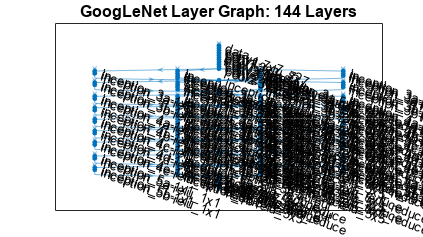

% This code is setting up a convolutional neural network (CNN) using GoogLeNet architecture 
% to classify ECG signals based on their CWT (continuous wavelet transform) image representations. 
% It first loads the pre-trained GoogLeNet network and visualizes its architecture. 
% Then, it replaces the final layers of the network with a dropout layer, 
% a fully connected layer with a learn rate factor of 5, and a classification layer. 
% It sets up the training options for the network, 
% including using the stochastic gradient descent with momentum (SGDM) optimizer, 
% a mini-batch size of 15, a maximum of 20 epochs for training, an initial learning rate of 1e-4, 
% and validation data with a validation frequency of 10. 
% Finally, it sets the random number generator to default.

%for cwt images
net = googlenet;

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);


net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       40.00% |       34.00% |       2.3579 |       1.2653 |      1.0000e-04 |
|       1 |          10 |       00:00:40 |       53.33% |       52.67% |       1.3524 |       0.9313 |      1.0000e-04 |
|       2 |          20 |       00:01:08 |       46.67% |       70.00% |       1.1752 |       0.7369 |      1.0000e-04 |
|       3 |          30 |       00:01:35 |       60.00% |       79.33% |       0.6563 |       0.5661 |      1.0000

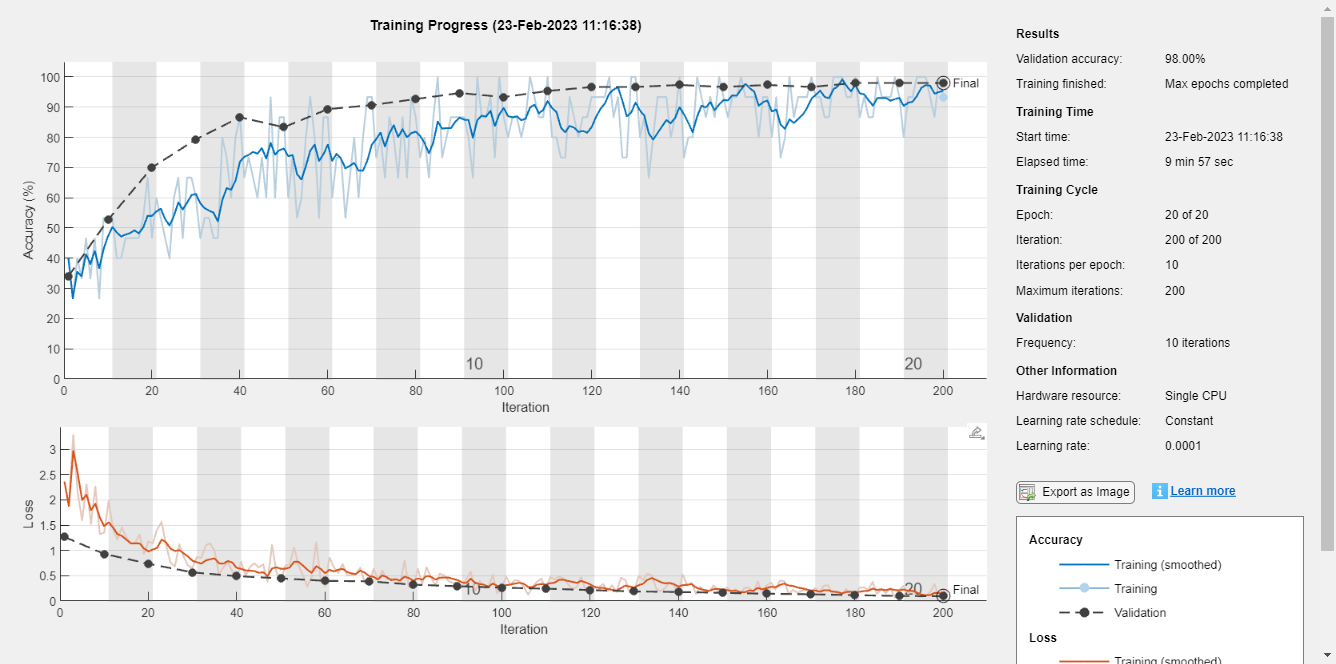

GoogLeNet Accuracy for cwt images: 98%



newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);


numClasses = numel(categories(TrainImages_cwt.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options_cwt = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',TestImages_cwt_aug,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default


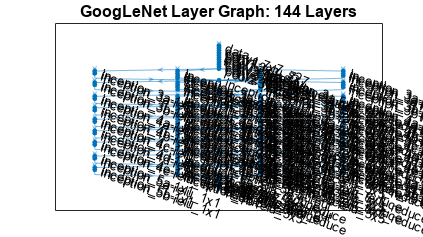

% In this code, a new instance of the GoogLeNet convolutional neural network is created 
% and its layers are modified to fine-tune the network for the STFT images.
% The layerGraph function is used to create a graph object representing the GoogLeNet architecture. 
% Then, a new dropout layer is added with a dropout rate of 0.6. 
% The replaceLayer function is used to replace the original dropout layer with the new one.
% Next, a new fully connected layer is added with the number of output neurons set 
% to the number of classes in the STFT images dataset. 
% The replaceLayer function is again used to replace 
% the original fully connected layer with the new one.
% Finally, a new classification layer is added 
% to the end of the network using the replaceLayer function. 
% The trainingOptions function is used to set the options for training the modified network, 
% including the optimization algorithm, mini-batch size, number of epochs, and learning rate.
% The rng function is used to set the random number generator 
% to its default state to ensure that the results are reproducible

%for stft images
net = googlenet;

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);


net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       33.33% |       20.67% |       1.6458 |       1.3866 |      1.0000e-04 |
|       1 |          10 |       00:00:38 |       46.67% |       48.00% |       1.7060 |       1.1448 |      1.0000e-04 |
|       2 |          20 |       00:01:05 |       80.00% |       65.33% |       0.6887 |       0.7823 |      1.0000e-04 |
|       3 |          30 |       00:01:32 |       80.00% |       74.67% |       0.6409 |       0.6476 |      1.0000

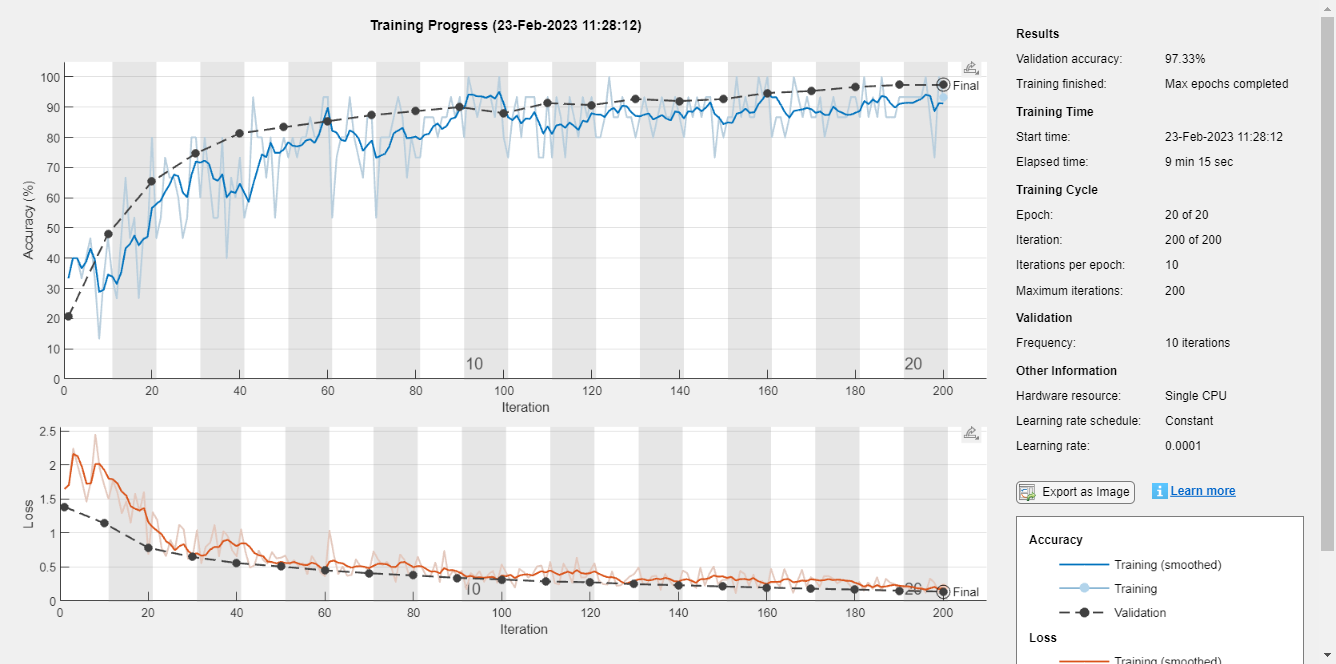

GoogLeNet Accuracy for stft images: 98%



newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);


numClasses = numel(categories(TrainImages_stft.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options_stft = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',TestImages_stft_aug,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default


### SqueezeNet (net2` = squeezenet`)

% These are code snippets for training two different versions of the SqueezeNet model 
% on two different datasets. 
% The second snippet trains the SqueezeNet model on a dataset of Short-Time Fourier Transform (STFT) images,
% while the first snippet trains the same model on a dataset of Continuous Wavelet Transform (CWT) images.
% The code first constructs a layer graph for the SqueezeNet model, 
% then modifies it by replacing some layers (e.g., dropout layer, fully connected layer) 
% and adding new layers (e.g., convolutional layer, classification layer) for fine-tuning.
% The code also sets various training options, 
% such as the learning rate, mini-batch size, maximum number of epochs, and validation data, 
% and trains the model using the specified options.
% The rng default command sets the random number generator to its default state 
% to ensure reproducibility of the results.

sqz = squeezenet;

lgraphSqz_cwt = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz_cwt.Layers))])

Number of Layers: 68



disp(lgraphSqz_cwt.Layers(1).InputSize)

   227   227     3




lgraphSqz_cwt.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes


tmpLayer = lgraphSqz_cwt.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz_cwt = replaceLayer(lgraphSqz_cwt,tmpLayer.Name,newDropoutLayer);

numClasses = numel(categories(TrainImages_cwt.Labels));
tmpLayer = lgraphSqz_cwt.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz_cwt = replaceLayer(lgraphSqz_cwt,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz_cwt.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz_cwt = replaceLayer(lgraphSqz_cwt,tmpLayer.Name,newClassLayer);

lgraphSqz_cwt.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          2-D Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       60.00% |       29.33% |       2.5090 |       2.7594 |          0.0003 |
|       1 |          50 |       00:00:36 |       40.00% |              |       1.0384 |              |          0.0003 |
|       1 |          75 |       00:00:55 |       70.00% |       50.67% |       0.8576 |       0.9918 |          0.0003 |
|       2 |         100 |       00:01:10 |       80.00% |              |       0.8461 |              |          0.

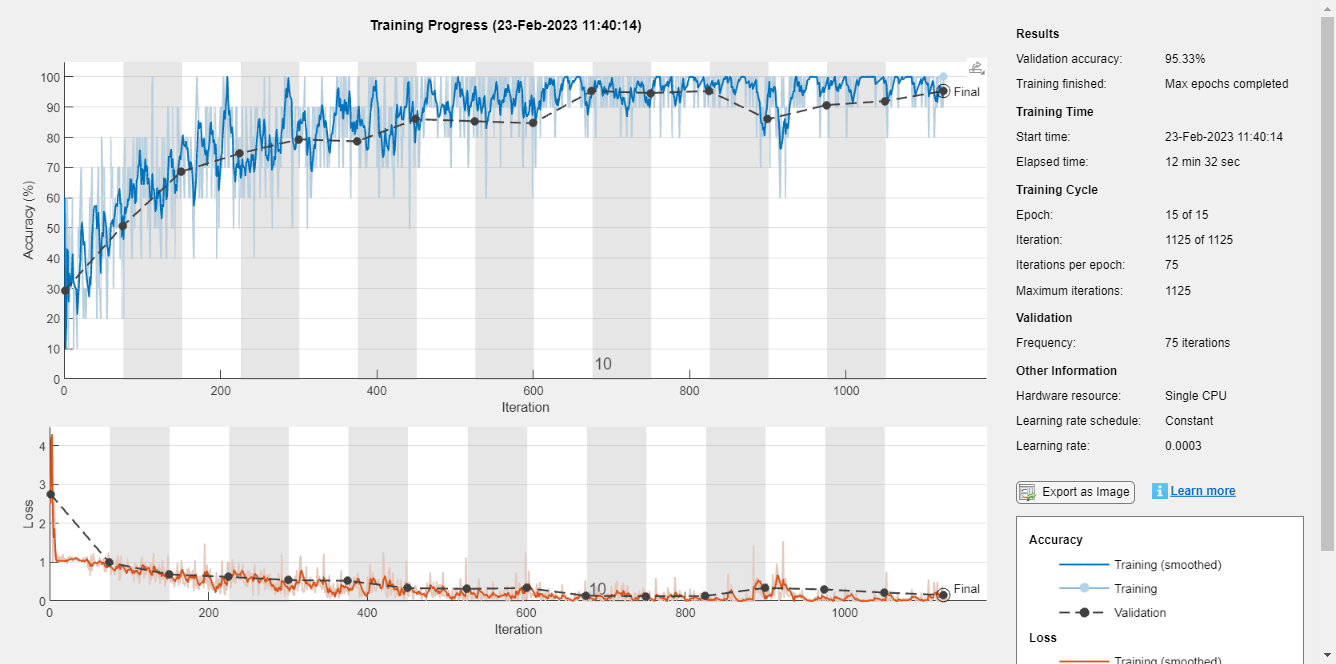

SqueezeNet Accuracy for cwt images: 95.3333%



augimgsTrain_cwt = augmentedImageDatastore([227 227],TrainImages_cwt);
augimgsValidation_cwt = augmentedImageDatastore([227 227],TestImages_cwt);

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain_cwt  .Files)/miniBatchSize);
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation_cwt,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default



sqz = squeezenet;

lgraphSqz_stft = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz_stft.Layers))])

Number of Layers: 68



disp(lgraphSqz_stft.Layers(1).InputSize)

   227   227     3




lgraphSqz_stft.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes


tmpLayer = lgraphSqz_stft.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz_stft = replaceLayer(lgraphSqz_stft,tmpLayer.Name,newDropoutLayer);

numClasses = numel(categories(TrainImages_stft.Labels));
tmpLayer = lgraphSqz_stft.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz_stft = replaceLayer(lgraphSqz_stft,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz_stft.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz_stft = replaceLayer(lgraphSqz_stft,tmpLayer.Name,newClassLayer);

lgraphSqz_stft.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          2-D Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       30.00% |       27.33% |       1.7894 |       1.5009 |          0.0003 |
|       1 |          50 |       00:00:35 |       50.00% |              |       0.9056 |              |          0.0003 |
|       1 |          75 |       00:00:53 |       80.00% |       82.67% |       0.4946 |       0.5251 |          0.0003 |
|       2 |         100 |       00:01:08 |       80.00% |              |       0.5854 |              |          0.

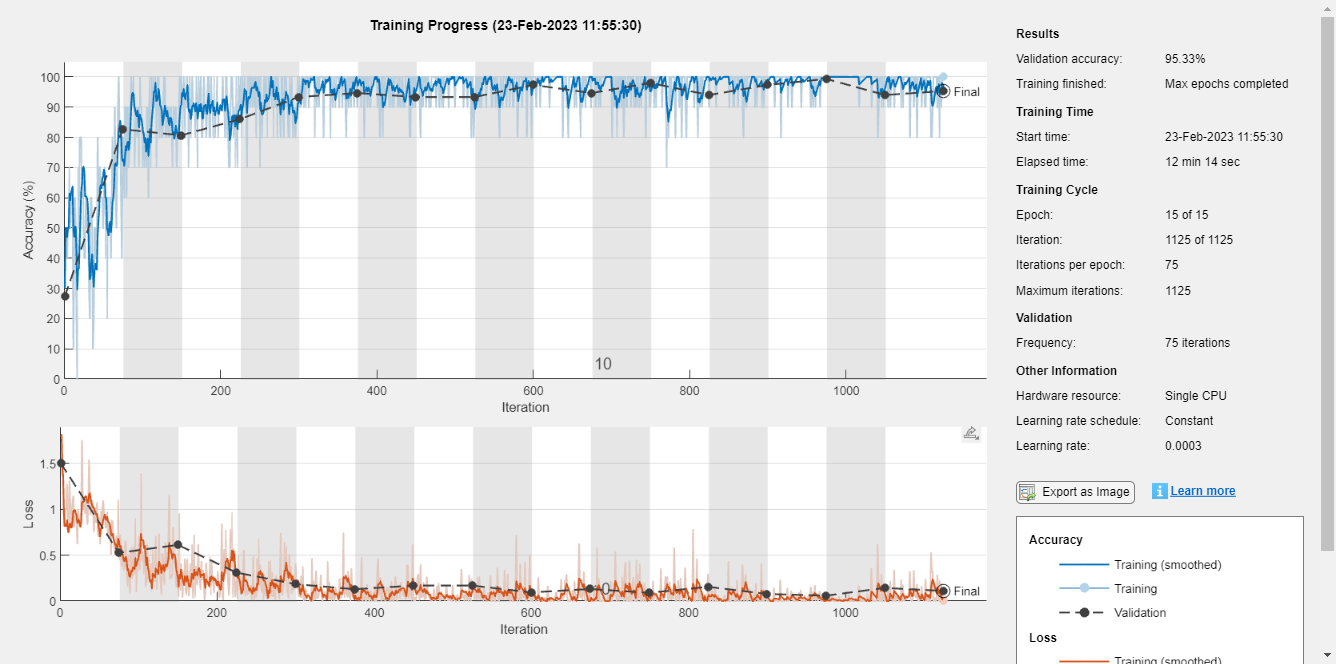

SqueezeNet Accuracy for stft images: 95.3333%



augimgsTrain_stft = augmentedImageDatastore([227 227],TrainImages_stft);
augimgsValidation_stft = augmentedImageDatastore([227 227],TestImages_stft);

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain_stft  .Files)/miniBatchSize);
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation_stft,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default


### AlexNet (net3 = alexnet)

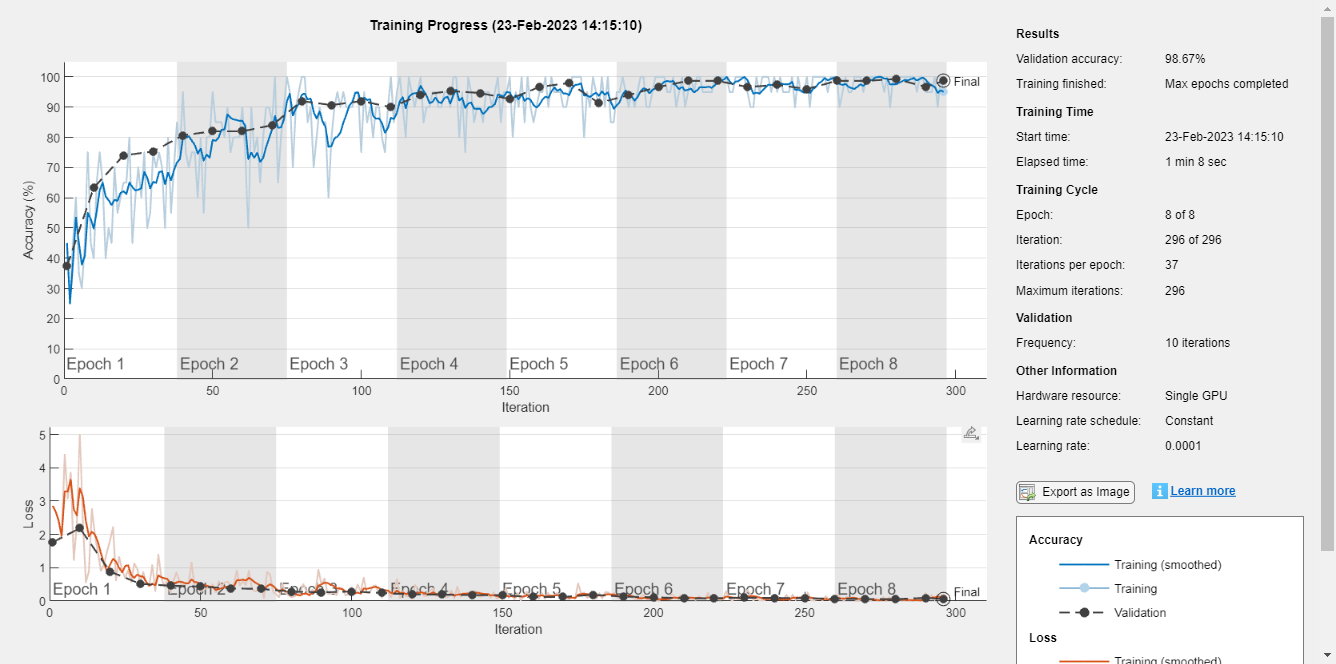

% This code trains and validates two separate AlexNet models using two different image datasets: 
% one using images in the time-frequency domain represented using the continuous wavelet transform (CWT), 
% and the other using images in the time-frequency domain represented 
% using the short-time Fourier transform (STFT).
% First, the code reads the images from the specified directory using the imageDatastore function 
% and then splits them into training and testing sets using the splitEachLabel function.
% Next, the pre-trained AlexNet model is imported and all layers except the last three are preserved. 
% Two fully connected layers are then added to the end of the network, followed by a softmax layer 
% and a classification layer.
% Finally, the code defines the training options for the two models using the trainingOptions function. 
% The options include the use of stochastic gradient descent with a mini-batch size of 20, 
% a maximum of 8 epochs, an initial learning rate of 1e-4, shuffling the data every epoch, validation data, 
% and frequency of validation checks. 
% The training progress is displayed using plots.

%training and validation using alexnet
DatasetPath = 'C:\Users\charan sammeta\Desktop\DSP\project\ecgdataset';
%Reading images from image database folder
images_cwt = imageDatastore(DatasetPath, "IncludeSubfolders",true,'LabelSource','foldernames');
%Distributing images in the set of training and testing
numTrainFiles = 250;
[TrainImages_cwt_anet, TestImages_cwt_anet] = splitEachLabel(images_cwt,numTrainFiles,'randomized');


%training and validation using alexnet
DatasetPath = 'C:\Users\charan sammeta\Desktop\DSP\project\ecgdataset';
%Reading images from image database folder
images_stft = imageDatastore(DatasetPath, "IncludeSubfolders",true,'LabelSource','foldernames');
%Distributing images in the set of training and testing
numTrainFiles = 250;
[TrainImages_stft_anet, TestImages_stft_anet] = splitEachLabel(images_stft,numTrainFiles,'randomized');

net = alexnet;  %Improting pretrained Alexnet
layersTransfer = net.Layers(1: end-3);   % preserving all layers except last three
numClasses=3; %Number of output classes: ARR, CHF, NSR
%Defining layers of Alexnet
layers = [layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

%training options
options_cwt_anet = trainingOptions('sgdm','MiniBatchSize',20,'MaxEpochs',8, ...
    'InitialLearnRate',1e-4,'Shuffle','every-epoch','ValidationData',TestImages_cwt_anet, ...
    'ValidationFrequency',10,'Verbose',false,'Plots','training-progress');


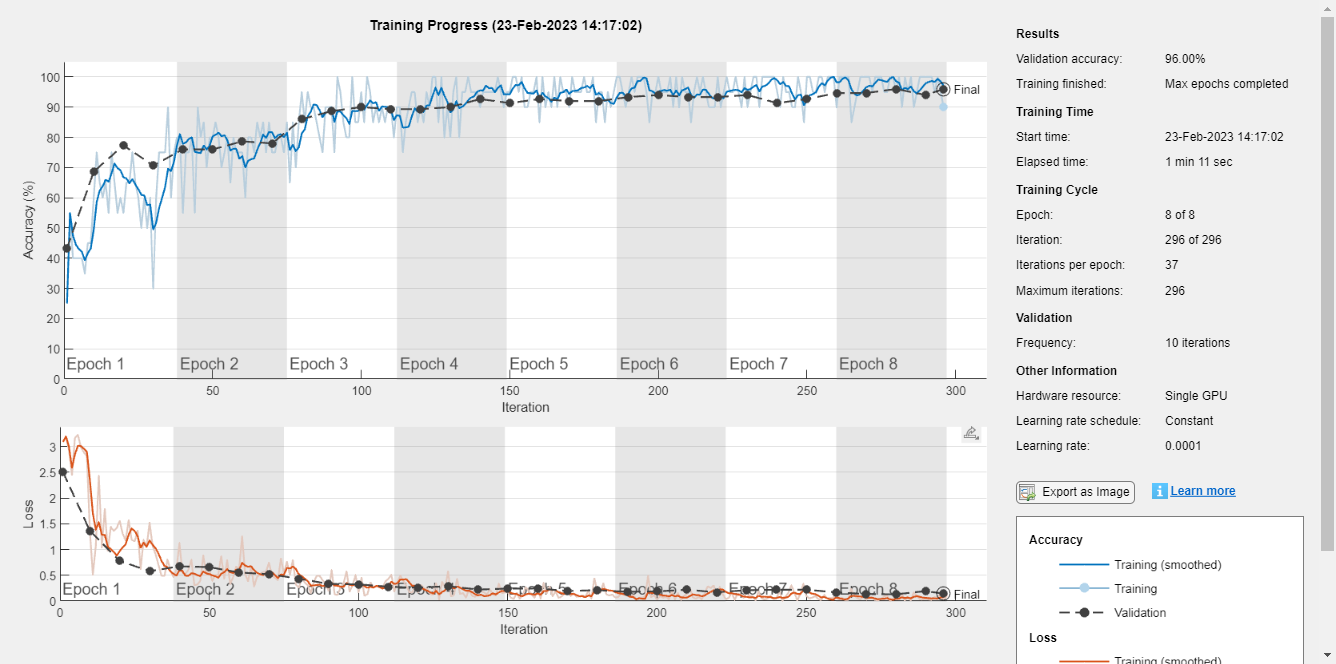

accuracy_cwt_anet =     0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693


accuracy_stft_anet =     0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640




%training options
options_stft_anet = trainingOptions('sgdm','MiniBatchSize',20,'MaxEpochs',8, ...
    'InitialLearnRate',1e-4,'Shuffle','every-epoch','ValidationData',TestImages_stft_anet, ...
    'ValidationFrequency',10,'Verbose',false,'Plots','training-progress');


## Train the Networks

% These lines of code are training and saving two different models using transfer learning 
% with AlexNet architecture. 
% The first two models are trained using a custom network architecture (trainedGN_cwt and trainedGN_stft)
% while the next two models are trained using a SqueezeNet architecture (trainedSN_cwt and trainedSN_stft).
% The last two models (netTransfer_cwt_anet and netTransfer_stft_anet) are trained 
% using the AlexNet architecture.
% The trainNetwork function is used to train the models with the respective training sets, 
% pre-defined network architectures, and training options. 
% The trained models are then saved for later use using the save function. 
% The options_cwt_anet and options_stft_anet are the training options for the two AlexNet models,
% respectively.

trainedGN_cwt = trainNetwork(TrainImages_cwt_aug,lgraph,options_cwt);
save trainedGN_cwt


GoogLeNet Accuracy for cwt images: 98%


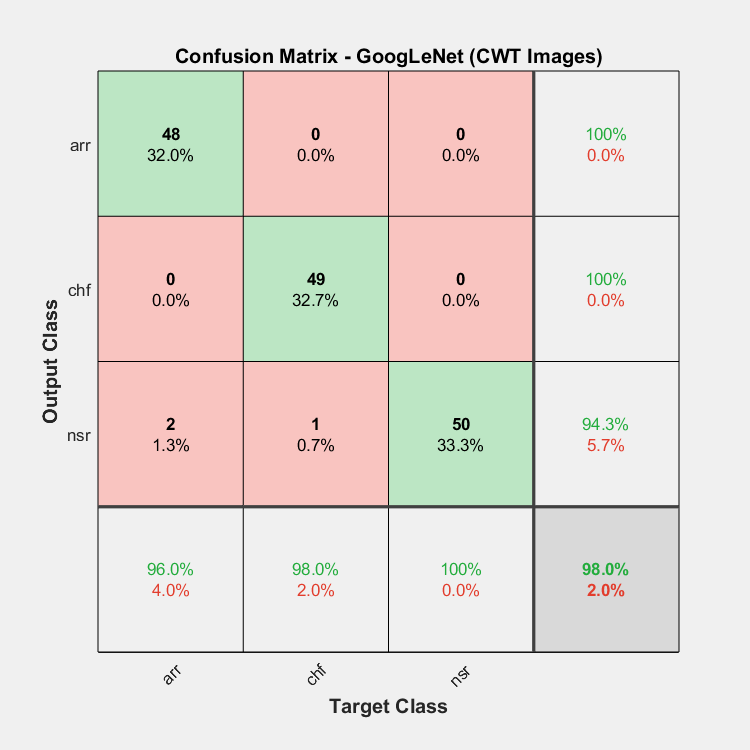

trainedGN_stft = trainNetwork(TrainImages_stft_aug,lgraph,options_stft);
save trainedGN_stft

trainedSN_cwt = trainNetwork(augimgsTrain_cwt,lgraphSqz_cwt,opts);
save trainedSN_cwt


trainedSN_stft = trainNetwork(augimgsTrain_stft,lgraphSqz_stft,opts);
save trainedSN_stft

%Training the alexnet

GoogLeNet Accuracy for stft images: 97.3333%


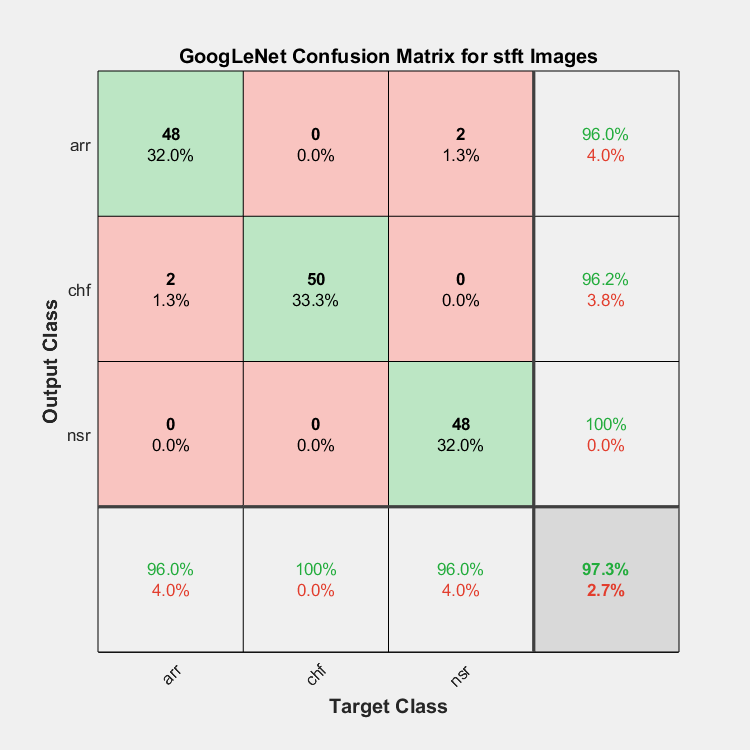

netTransfer_cwt_anet = trainNetwork(TrainImages_cwt_anet,layers,options_cwt_anet);
save netTransfer_cwt_anet

%Training the alexnet

netTransfer_stft_anet = trainNetwork(TrainImages_stft_anet,layers,options_stft_anet);
save netTransfer_stft_anet

## Test and validate the Networks -- Confusion Charts

Compare the results and the reliabilty of the different Time and Frequency Representations and the different Networks. Explain the differences!

% The above code is performing image classification using two different neural networks (GoogLeNet) 
% trained on two different types of spectrogram images (continuous wavelet transform (CWT) 
% and short-time Fourier transform (STFT)) for bird species identification.
% The code first predicts the labels of the test images using the trained GoogLeNet model 
% for CWT and STFT spectrogram images separately. 
% Then, the accuracy of the predictions is computed and displayed using the mean function and disp function.
% Finally, the confusion matrices for both the CWT and STFT GoogLeNet models 
% are plotted using the plotconfusion function to visualize 
% the performance of the models in terms of classification accuracy and misclassifications.
% The confusion matrices show the true and predicted labels on the vertical and horizontal axes, 
% respectively, 
% and the diagonal cells represent the number of correctly classified samples for each class, 
% while the off-diagonal cells represent misclassifications.


[YPred_cwt_gnet,probs] = classify(trainedGN_cwt,TestImages_cwt_aug);
accuracy_cwt_gnet = mean(YPred_cwt_gnet==TestImages_cwt.Labels);
disp(['GoogLeNet Accuracy for cwt images: ',num2str(100*accuracy_cwt_gnet),'%'])

SqueezeNet Accuracy for cwt images: 95.3333%


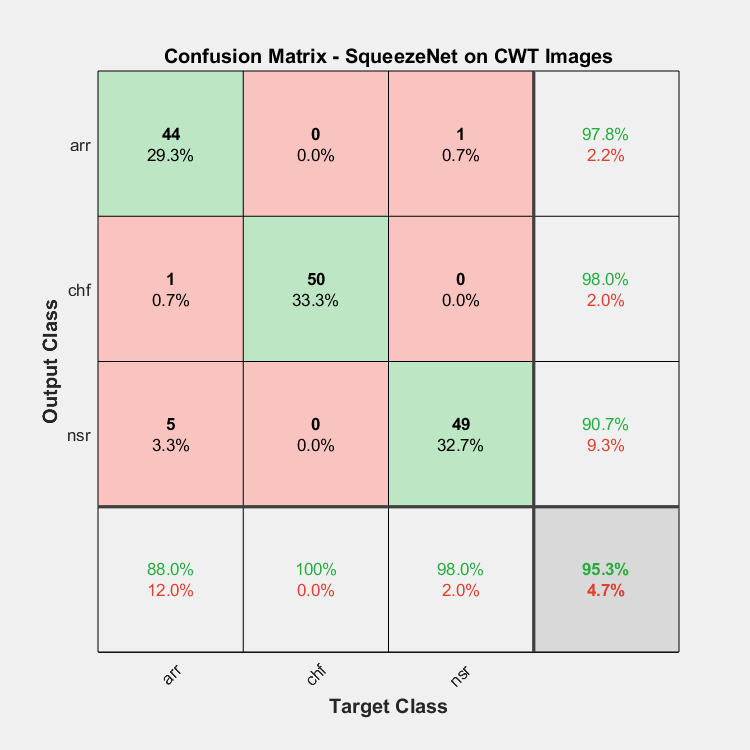


% Plot confusion matrix
figure
plotconfusion(TestImages_cwt.Labels, YPred_cwt_gnet);

title('Confusion Matrix - GoogLeNet (CWT Images)');


[YPred_stft_gnet,probs] = classify(trainedGN_stft,TestImages_stft_aug);
accuracy_stft_gnet = mean(YPred_stft_gnet==TestImages_stft.Labels);
disp(['GoogLeNet Accuracy for stft images: ',num2str(100*accuracy_stft_gnet),'%'])

SqueezeNet Accuracy for stft images: 95.3333%


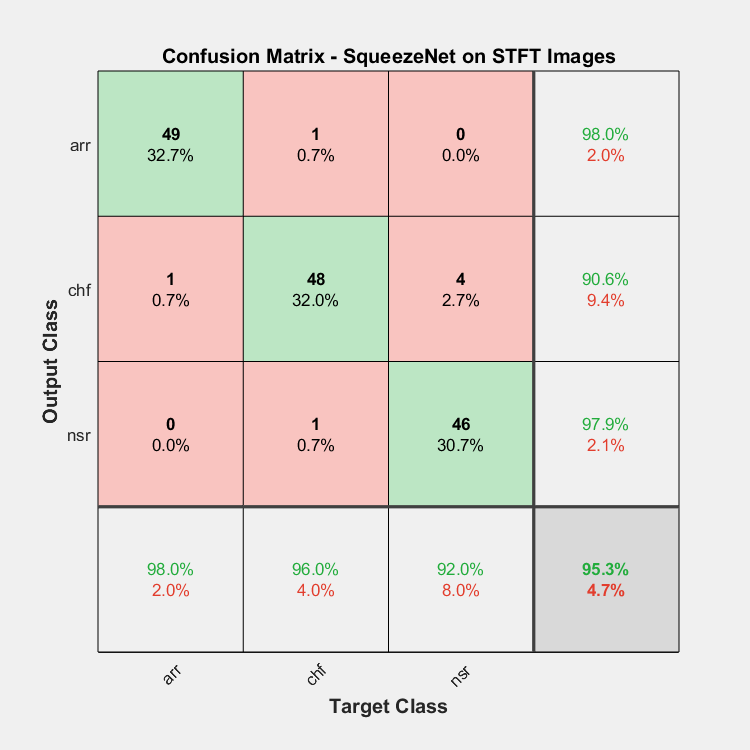


figure
plotconfusion(TestImages_stft.Labels,YPred_stft_gnet);
title('GoogLeNet Confusion Matrix for stft Images');

% The above code is evaluating the accuracy of the SqueezeNet model on the validation set of 
% CWT and STFT images, and then generating confusion matrices for both.
% First, it uses the trained SqueezeNet model trainedSN_cwt to 
% classify the validation set of CWT images augimgsValidation_cwt. 
% The classify function returns the predicted labels YPred_cwt and the probabilities probs.
% The code then calculates the accuracy of the SqueezeNet model on the CWT images 
% using mean(YPred_cwt==TestImages_cwt.Labels) and displays it using disp.
% Next, the code generates a confusion matrix for the CWT images using 
% the plotconfusion function, which takes the true labels (TestImages_cwt.Labels) and 
% predicted labels (YPred_cwt) as arguments. 
% The title function is used to add a title to the plot.
% The same process is then repeated for the validation set of STFT images 
% using the trained SqueezeNet model trainedSN_stft.


accuracy_cwt_anet =     0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693    0.0693


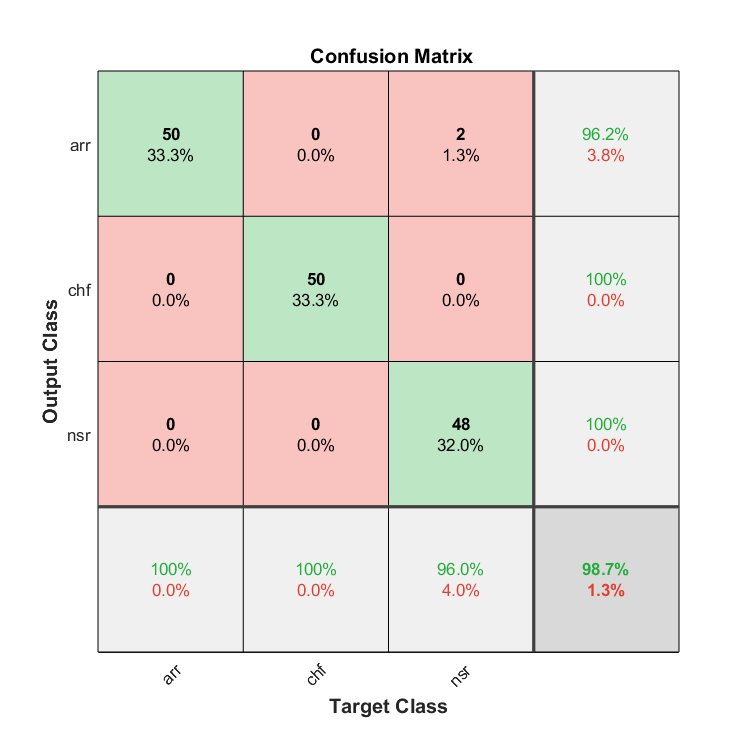



[YPred_cwt,probs] = classify(trainedSN_cwt,augimgsValidation_cwt);

accuracy_cwt_snet = mean(YPred_cwt==TestImages_cwt.Labels);
disp(['SqueezeNet Accuracy for cwt images: ',num2str(100*accuracy_cwt_snet),'%'])

figure
plotconfusion(TestImages_cwt.Labels, YPred_cwt)

accuracy_stft_anet =     0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640    0.0640


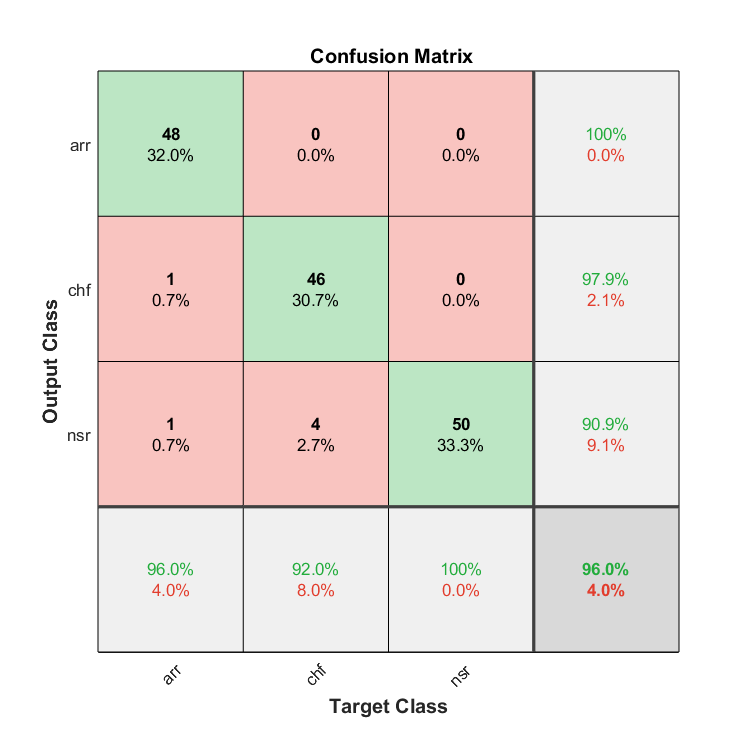

title('Confusion Matrix - SqueezeNet on CWT Images')




[YPred_stft,probs] = classify(trainedSN_stft,augimgsValidation_stft);
accuracy_stft_snet = mean(YPred_stft==TestImages_stft.Labels);
disp(['SqueezeNet Accuracy for stft images: ',num2str(100*accuracy_stft_snet),'%'])

figure
plotconfusion(TestImages_stft.Labels, YPred_stft)
title('Confusion Matrix - SqueezeNet on STFT Images')

% This code is performing image classification using transfer learning with AlexNet 
% on two sets of spectrogram images: CWT (continuous wavelet transform) and 
% STFT (short-time Fourier transform).

Fs = 256

% For CWT images, the code first classifies the images using classify function 
% with the fine-tuned AlexNet model netTransfer_cwt_anet, 

my_window =     0.0800
    0.0801
    0.0806
    0.0813
    0.0822
    0.0835
    0.0850
    0.0868
    0.0889
    0.0913


% and calculates the accuracy using sum and numel functions.
% Then, it reshapes the test image labels and plots the confusion matrix using plotconfusion function.
% The same process is repeated for STFT images, where the model used is netTransfer_stft_anet

%classifying images cwt for alexnet
YPred_cwt_anet = classify(netTransfer_cwt_anet, TestImages_cwt_anet);
YValidation_cwt_anet = TrainImages_cwt_anet.Labels;
accuracy_cwt_anet = sum(YPred_cwt_anet == YValidation_cwt_anet')/numel(YValidation_cwt_anet)
%plotting confusion matrix for cwt images
YValidation_cwt_anet = reshape(TestImages_cwt_anet.Labels, [], 1);
plotconfusion(YValidation_cwt_anet,YPred_cwt_anet)

%classifying images stft for alexnet
YPred_stft_anet = classify(netTransfer_stft_anet, TestImages_stft_anet);
YValidation_stft_anet = TrainImages_stft_anet.Labels;
accuracy_stft_anet = sum(YPred_stft_anet == YValidation_stft_anet')/numel(YValidation_stft_anet)
%plotting confusion matrix for stft images
YValidation_stft_anet = reshape(TestImages_stft_anet.Labels, [],1);
plotconfusion(YValidation_stft_anet,YPred_stft_anet)

## Apply the Networks to given ECG Signal

% In this code snippet, a given ECG signal is transformed using 
% the Short-Time Fourier Transform (STFT) and Continuous Wavelet Transform (CWT) 

     Class according to GoogLeNet:      nsr 



% to obtain spectrogram and wavelet transformed images, respectively. 
% The resulting images are then resized to 224x224 and 227x227 pixels 
% and classified using three pre-trained CNN models: GoogLeNet, SqueezeNet, and AlexNet. 

     Class according to SqueezeNet:      nsr 



% The classification results for each CNN model are displayed on the console. 
% The same process is repeated for both STFT and CWT transformed images.


     Class according to AlexNet: chf 



Fs = 256
% STFT for the given image
my_window = hamming(256)
%data = ecg.data'
%[img,f,t] = spectrogram(ecg,data(1,1:8000),my_window,128,256,Fs);

     Class according to GoogLeNet:      chf 



[img,f,t] = spectrogram(ecg.data(1:100000),my_window,128,256,Fs);
% create jpg-image
ecg_stft = ind2rgb(im2uint8(rescale(10*log10(abs(img)))),jet(128));

     Class according to SqueezeNet:      chf 



ecg_stft_224 = imresize(ecg_stft,[224 224]);
%imwrite(ecg_stft_224,"fig2.jpg")
ecg_stft_227 = imresize(ecg_stft,[227  227]);

     Class according to AlexNet: chf 



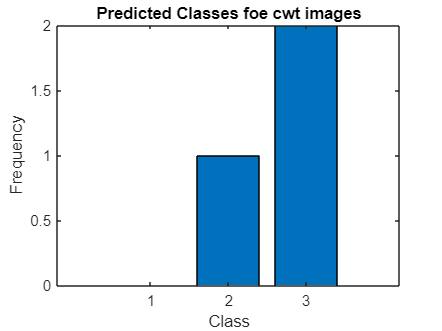


% Wavelet transformation for the given image
%[signalLength,~] = size(ecg.data)
fb = cwtfilterbank('SignalLength',100000,'VoicesPerOctave',12);
ecg_temp = abs(fb.wt(ecg.data(1:100000)));
ecg_wavelet = ind2rgb(im2uint8(rescale(ecg_temp)),jet(128));
ecg_wavelet_224 = imresize(ecg_wavelet,[224 224]);
ecg_wavelet_227 = imresize(ecg_wavelet,[227 227]);

% Classify the wavelet transformed image with all three CNNs
% GoogLeNet: 
[YPred_gnet_cwt,info_gnet] = classify(trainedGN_cwt,ecg_wavelet_224);
disp(['Class according to GoogLeNet: ',YPred_gnet_cwt])
% SqueezeNet: 
[YPred_sqznet_cwt,info_sqznet] = classify(trainedSN_cwt,ecg_wavelet_227);
disp(['Class according to SqueezeNet: ',YPred_sqznet_cwt])
% AlexNet: 
[YPred_alxnet_cwt,info_alxnet] = classify(netTransfer_cwt_anet,ecg_wavelet_227);
disp(['Class according to AlexNet: ',YPred_alxnet_cwt])

% Classify the wavelet transformed image with all three CNNs
% GoogLeNet: 
[YPred_gnet_stft,info_gnet] = classify(trainedGN_stft,ecg_wavelet_224);
disp(['Class according to GoogLeNet: ',YPred_gnet_stft])
% SqueezeNet: 
[YPred_sqznet_stft,info_sqznet] = classify(trainedSN_stft,ecg_wavelet_227);
disp(['Class according to SqueezeNet: ',YPred_sqznet_stft])
% AlexNet: 

[YPred_alxnet_stft,info_alxnet] = classify(netTransfer_stft_anet,ecg_wavelet_227);
disp(['Class according to AlexNet: ',YPred_alxnet_stft])



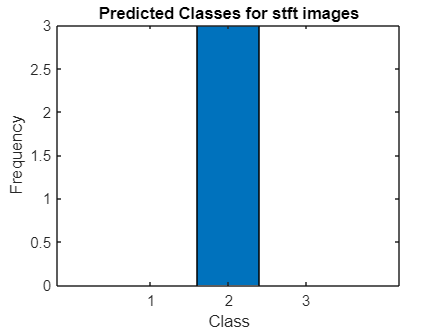

% These lines of code are analyzing the predictions made by the three CNNs 
% (GoogLeNet, SqueezeNet, and AlexNet) on the test images transformed using CWT and STFT.

% First, the code concatenates the predictions from all three CNNs into two separate vectors: 
% YPred_all_cwt for the CWT-transformed images and YPred_all_stft for the STFT-transformed images. 
% Then, the frequency of each predicted class is counted using the countcats function, 
% and the results are plotted as a bar graph using the bar function.
% There are two bar graphs generated, one for the CWT-transformed images 
% and another for the STFT-transformed images. 
% The x-axis of each graph represents the classes (i.e., the different heart rhythms), 
% while the y-axis represents the frequency of predictions made for each class. 
% The title of each graph indicates whether it is for CWT or STFT images.


% Concatenate the predictions from all CNNs
YPred_all_cwt = [YPred_gnet_cwt YPred_sqznet_cwt YPred_alxnet_cwt];
YPred_all_stft = [YPred_gnet_stft YPred_sqznet_stft YPred_alxnet_stft];
% Count the frequency of each predicted class
class_counts_cwt = countcats(categorical(YPred_all_cwt));
class_counts_stft = countcats(categorical(YPred_all_stft));
% Create a bar graph of the class frequencies
figure 
bar(class_counts_cwt)
xlabel('Class')
ylabel('Frequency')
title('Predicted Classes for cwt images')

figure 
bar(class_counts_stft)
xlabel('Class')
ylabel('Frequency')
title('Predicted Classes for stft images')
